% Add path
addpath(genpath('.\Motion'));
addpath(genpath('.\Registration'));
addpath(genpath('.\SVD'));
addpath(genpath('.\KeyPoints'));

clear;
clc;

% Preview motion data to manually select indexes
% Oral Task: maximum open and close, choose by z-axis
% Oral Task: lateral left-right movement, choose by x-axis
% Oral Task: anterior-posterior movement, choose by y-axis

% Params
preopDataPath = 'C:\Users\Yaolab\Box\6monthVs.12month\Cases\CARSH_00177\11-24-2020\';
postopDataPath = 'C:\Users\Yaolab\Box\6monthVs.12month\Cases\CARSH_00177\07-16-2021\';
postop2DataPath = 'C:\Users\Yaolab\Box\6monthVs.12month\Cases\CARSH_00177\12-16-2021\';

preopMotionDataCSVFilePath   = [preopDataPath, 'Motion_csv\11.csv'];       % Motion data path
postopMotionDataCSVFilePath   = [postopDataPath, 'Motion_csv\11.csv'];       % Motion data path
postop2MotionDataCSVFilePath   = [postop2DataPath, 'Motion_csv\11.csv'];       % Motion data path

preopSkullGeomagicMarkersPath = [preopDataPath, 'GeomagicFiles\Skull_Markers_Coordinates.csv'];
postopSkullGeomagicMarkersPath = [postopDataPath, 'GeomagicFiles\Skull_Markers_Coordinates.csv'];
postop2SkullGeomagicMarkersPath = [postop2DataPath, 'GeomagicFiles\Skull_Markers_Coordinates.csv'];
preopTitleStr = 'Maximum open and close';             % Name of oral task
postopTitleStr = 'Maximum open and close';             % Name of oral task
postop2TitleStr = 'Maximum open and close';             % Name of oral task

% Read motion data from the CSV file
m_preopMotionData = loadMotionCSVData(preopMotionDataCSVFilePath);

Frame: missing 0 out of 2608 data.
TypeNameTimeSeconds: missing 0 out of 2608 data.
RigidBodyMandibleRotationX: missing 280 out of 2608 data.
RigidBodyMandibleRotationY: missing 280 out of 2608 data.
RigidBodyMandibleRotationZ: missing 280 out of 2608 data.
RigidBodyMandibleRotationW: missing 280 out of 2608 data.
RigidBodyMandiblePositionX: missing 280 out of 2608 data.
RigidBodyMandiblePositionY: missing 280 out of 2608 data.
RigidBodyMandiblePositionZ: missing 280 out of 2608 data.
RigidBodyMandibleMeanMarkerError: missing 280 out of 2608 data.
RigidBodyMarkerMandibleMarker1PositionX: missing 280 out of 2608 data.
RigidBodyMarkerMandibleMarker1PositionY: missing 280 out of 2608 data.
RigidBodyMarkerMandibleMarker1PositionZ: missing 280 out of 2608 data.
RigidBodyMarkerMandibleMarker1MarkerQuality: missing 280 out of 2608 data.
RigidBodyMarkerMandibleMarker2PositionX: missing 280 out of 2608 data.
RigidBodyMarkerMandibleMarker2PositionY: missing 280 out of 2608 data.
RigidBodyMarkerM

m_postopMotionData = loadMotionCSVData(postopMotionDataCSVFilePath);

Frame: missing 0 out of 1782 data.
TypeNameTimeSeconds: missing 0 out of 1782 data.
RigidBodyMandibleRotationX: missing 7 out of 1782 data.
RigidBodyMandibleRotationY: missing 7 out of 1782 data.
RigidBodyMandibleRotationZ: missing 7 out of 1782 data.
RigidBodyMandibleRotationW: missing 7 out of 1782 data.
RigidBodyMandiblePositionX: missing 7 out of 1782 data.
RigidBodyMandiblePositionY: missing 7 out of 1782 data.
RigidBodyMandiblePositionZ: missing 7 out of 1782 data.
RigidBodyMandibleMeanMarkerError: missing 7 out of 1782 data.
RigidBodyMarkerMandibleMarker1PositionX: missing 7 out of 1782 data.
RigidBodyMarkerMandibleMarker1PositionY: missing 7 out of 1782 data.
RigidBodyMarkerMandibleMarker1PositionZ: missing 7 out of 1782 data.
RigidBodyMarkerMandibleMarker1MarkerQuality: missing 7 out of 1782 data.
RigidBodyMarkerMandibleMarker2PositionX: missing 7 out of 1782 data.
RigidBodyMarkerMandibleMarker2PositionY: missing 7 out of 1782 data.
RigidBodyMarkerMandibleMarker2PositionZ: mis

m_postop2MotionData = loadMotionCSVData(postop2MotionDataCSVFilePath);

Frame: missing 0 out of 2366 data.
TypeNameTimeSeconds: missing 0 out of 2366 data.
RigidBodyMandibleRotationX: missing 43 out of 2366 data.
RigidBodyMandibleRotationY: missing 43 out of 2366 data.
RigidBodyMandibleRotationZ: missing 43 out of 2366 data.
RigidBodyMandibleRotationW: missing 43 out of 2366 data.
RigidBodyMandiblePositionX: missing 43 out of 2366 data.
RigidBodyMandiblePositionY: missing 43 out of 2366 data.
RigidBodyMandiblePositionZ: missing 43 out of 2366 data.
RigidBodyMandibleMeanMarkerError: missing 43 out of 2366 data.
RigidBodyMarkerMandibleMarker1PositionX: missing 43 out of 2366 data.
RigidBodyMarkerMandibleMarker1PositionY: missing 43 out of 2366 data.
RigidBodyMarkerMandibleMarker1PositionZ: missing 43 out of 2366 data.
RigidBodyMarkerMandibleMarker1MarkerQuality: missing 43 out of 2366 data.
RigidBodyMarkerMandibleMarker2PositionX: missing 43 out of 2366 data.
RigidBodyMarkerMandibleMarker2PositionY: missing 43 out of 2366 data.
RigidBodyMarkerMandibleMarker2


% Read skull markers position in CBCT 
m_preopSkullGeomagicMarkers = loadSkullGeomagicPoints(preopSkullGeomagicMarkersPath);
m_postopSkullGeomagicMarkers = loadSkullGeomagicPoints(postopSkullGeomagicMarkersPath);
m_postop2SkullGeomagicMarkers = loadSkullGeomagicPoints(postop2SkullGeomagicMarkersPath);

% Reorder skull markers order based on relative distance relationship of markers
m_preopMotionData = reorderSkullMarkers(m_preopMotionData, m_preopSkullGeomagicMarkers);
m_postopMotionData = reorderSkullMarkers(m_postopMotionData, m_postopSkullGeomagicMarkers);
m_postop2MotionData = reorderSkullMarkers(m_postop2MotionData, m_postop2SkullGeomagicMarkers);

% Get mandible markers position based on skull markers in CBCT, skull
% markers in motion, mandible markers in motion
m_preopMandibleGeomagicPoints = registerMandibleBySkull(m_preopMotionData, m_preopSkullGeomagicMarkers);
m_postopMandibleGeomagicPoints = registerMandibleBySkull(m_postopMotionData, m_postopSkullGeomagicMarkers);
m_postop2MandibleGeomagicPoints = registerMandibleBySkull(m_postop2MotionData, m_postop2SkullGeomagicMarkers);

% Fix skull position based on skull markers in CBCT
m_preopMotionData = fixSkullMarkers(m_preopMotionData, m_preopSkullGeomagicMarkers);

Frame 1, Alignment accuracy: 14.069808
Frame 2, Alignment accuracy: 14.069808
Frame 3, Alignment accuracy: 14.069806
Frame 4, Alignment accuracy: 14.069804
Frame 5, Alignment accuracy: 14.069807
Frame 6, Alignment accuracy: 14.069809
Frame 7, Alignment accuracy: 14.069805
Frame 8, Alignment accuracy: 14.069807
Frame 9, Alignment accuracy: 14.069807
Frame 10, Alignment accuracy: 14.069807
Frame 11, Alignment accuracy: 14.069806
Frame 12, Alignment accuracy: 14.069809
Frame 13, Alignment accuracy: 14.069808
Frame 14, Alignment accuracy: 14.069807
Frame 15, Alignment accuracy: 14.069808
Frame 16, Alignment accuracy: 14.069807
Frame 17, Alignment accuracy: 14.069808
Frame 18, Alignment accuracy: 14.069809
Frame 19, Alignment accuracy: 14.069808
Frame 20, Alignment accuracy: 14.069807
Frame 21, Alignment accuracy: 14.069807
Frame 22, Alignment accuracy: 14.069807
Frame 23, Alignment accuracy: 14.069810
Frame 24, Alignment accuracy: 14.069807
Frame 25, Alignment accuracy: 14.069808
Frame 26,

m_postopMotionData = fixSkullMarkers(m_postopMotionData, m_postopSkullGeomagicMarkers);

Frame 1, Alignment accuracy: 0.505788
Frame 2, Alignment accuracy: 0.505788
Frame 3, Alignment accuracy: 0.505788
Frame 4, Alignment accuracy: 0.505789
Frame 5, Alignment accuracy: 0.505790
Frame 6, Alignment accuracy: 0.505791
Frame 7, Alignment accuracy: 0.505789
Frame 8, Alignment accuracy: 0.505789
Frame 9, Alignment accuracy: 0.505790
Frame 10, Alignment accuracy: 0.505790
Frame 11, Alignment accuracy: 0.505790
Frame 12, Alignment accuracy: 0.505790
Frame 13, Alignment accuracy: 0.505785
Frame 14, Alignment accuracy: 0.505790
Frame 15, Alignment accuracy: 0.505791
Frame 16, Alignment accuracy: 0.505791
Frame 17, Alignment accuracy: 0.505791
Frame 18, Alignment accuracy: 0.505788
Frame 19, Alignment accuracy: 0.505789
Frame 20, Alignment accuracy: 0.505790
Frame 21, Alignment accuracy: 0.505789
Frame 22, Alignment accuracy: 0.505789
Frame 23, Alignment accuracy: 0.505791
Frame 24, Alignment accuracy: 0.505790
Frame 25, Alignment accuracy: 0.505790
Frame 26, Alignment accuracy: 0.50

m_postop2MotionData = fixSkullMarkers(m_postop2MotionData, m_postop2SkullGeomagicMarkers);

Frame 1, Alignment accuracy: 0.591803
Frame 2, Alignment accuracy: 0.591801
Frame 3, Alignment accuracy: 0.591801
Frame 4, Alignment accuracy: 0.591801
Frame 5, Alignment accuracy: 0.591802
Frame 6, Alignment accuracy: 0.591798
Frame 7, Alignment accuracy: 0.591803
Frame 8, Alignment accuracy: 0.591802
Frame 9, Alignment accuracy: 0.591802
Frame 10, Alignment accuracy: 0.591802
Frame 11, Alignment accuracy: 0.591802
Frame 12, Alignment accuracy: 0.591805
Frame 13, Alignment accuracy: 0.591802
Frame 14, Alignment accuracy: 0.591800
Frame 15, Alignment accuracy: 0.591803
Frame 16, Alignment accuracy: 0.591800
Frame 17, Alignment accuracy: 0.591809
Frame 18, Alignment accuracy: 0.591807
Frame 19, Alignment accuracy: 0.591804
Frame 20, Alignment accuracy: 0.591802
Frame 21, Alignment accuracy: 0.591798
Frame 22, Alignment accuracy: 0.591803
Frame 23, Alignment accuracy: 0.591801
Frame 24, Alignment accuracy: 0.591800
Frame 25, Alignment accuracy: 0.591804
Frame 26, Alignment accuracy: 0.59


% Filter motion data
m_preopMotionData = filterMotionData(m_preopMotionData);
m_postopMotionData = filterMotionData(m_postopMotionData);
m_postop2MotionData = filterMotionData(m_postop2MotionData);

% Smooth motion data
m_preopMotionData = smoothMotionData(m_preopMotionData);
m_postopMotionData = smoothMotionData(m_postopMotionData);
m_postop2MotionData = smoothMotionData(m_postop2MotionData);

% Load key points to track trajectory
preopSkullGeomagicPointsPath    = [preopDataPath, 'GeomagicFiles\Skull_Points_Coordinates.csv'];
postopSkullGeomagicPointsPath    = [postopDataPath, 'GeomagicFiles\Skull_Points_Coordinates.csv'];
postop2SkullGeomagicPointsPath    = [postop2DataPath, 'GeomagicFiles\Skull_Points_Coordinates.csv'];

preopMandibleGeomagicPointsPath = [preopDataPath, 'GeomagicFiles\Mandible_Points_Coordinates.csv'];
postopMandibleGeomagicPointsPath = [postopDataPath, 'GeomagicFiles\Mandible_Points_Coordinates.csv'];
postop2MandibleGeomagicPointsPath = [postop2DataPath, 'GeomagicFiles\Mandible_Points_Coordinates.csv'];

m_preopKeyGeomagicPoints = loadKeyGeomagicPoints(preopSkullGeomagicPointsPath, preopMandibleGeomagicPointsPath);
m_postopKeyGeomagicPoints = loadKeyGeomagicPoints(postopSkullGeomagicPointsPath, postopMandibleGeomagicPointsPath);
m_postop2KeyGeomagicPoints = loadKeyGeomagicPoints(postop2SkullGeomagicPointsPath, postop2MandibleGeomagicPointsPath);

% Compute trajectory based on motion data
m_preopKeyGeomagicPoints = computeKeyPointsTrajectory(m_preopMotionData, m_preopKeyGeomagicPoints);

Frame 2, Alignment accuracy: 0.000000
Frame 2, Alignment accuracy: 0.000001
Frame 3, Alignment accuracy: 0.000000
Frame 3, Alignment accuracy: 0.000001
Frame 4, Alignment accuracy: 0.000000
Frame 4, Alignment accuracy: 0.000002
Frame 5, Alignment accuracy: 0.000000
Frame 5, Alignment accuracy: 0.000002
Frame 6, Alignment accuracy: 0.000000
Frame 6, Alignment accuracy: 0.000003
Frame 7, Alignment accuracy: 0.000000
Frame 7, Alignment accuracy: 0.000003
Frame 8, Alignment accuracy: 0.000000
Frame 8, Alignment accuracy: 0.000003
Frame 9, Alignment accuracy: 0.000000
Frame 9, Alignment accuracy: 0.000004
Frame 10, Alignment accuracy: 0.000000
Frame 10, Alignment accuracy: 0.000004
Frame 11, Alignment accuracy: 0.000000
Frame 11, Alignment accuracy: 0.000004
Frame 12, Alignment accuracy: 0.000000
Frame 12, Alignment accuracy: 0.000004
Frame 13, Alignment accuracy: 0.000000
Frame 13, Alignment accuracy: 0.000004
Frame 14, Alignment accuracy: 0.000000
Frame 14, Alignment accuracy: 0.000005
Fr

m_postopKeyGeomagicPoints = computeKeyPointsTrajectory(m_postopMotionData, m_postopKeyGeomagicPoints);

Frame 2, Alignment accuracy: 0.000000
Frame 2, Alignment accuracy: 0.000001
Frame 3, Alignment accuracy: 0.000000
Frame 3, Alignment accuracy: 0.000001
Frame 4, Alignment accuracy: 0.000000
Frame 4, Alignment accuracy: 0.000001
Frame 5, Alignment accuracy: 0.000000
Frame 5, Alignment accuracy: 0.000001
Frame 6, Alignment accuracy: 0.000000
Frame 6, Alignment accuracy: 0.000001
Frame 7, Alignment accuracy: 0.000000
Frame 7, Alignment accuracy: 0.000001
Frame 8, Alignment accuracy: 0.000000
Frame 8, Alignment accuracy: 0.000001
Frame 9, Alignment accuracy: 0.000000
Frame 9, Alignment accuracy: 0.000001
Frame 10, Alignment accuracy: 0.000000
Frame 10, Alignment accuracy: 0.000001
Frame 11, Alignment accuracy: 0.000000
Frame 11, Alignment accuracy: 0.000001
Frame 12, Alignment accuracy: 0.000000
Frame 12, Alignment accuracy: 0.000001
Frame 13, Alignment accuracy: 0.000000
Frame 13, Alignment accuracy: 0.000001
Frame 14, Alignment accuracy: 0.000000
Frame 14, Alignment accuracy: 0.000001
Fr

m_postop2KeyGeomagicPoints = computeKeyPointsTrajectory(m_postop2MotionData, m_postop2KeyGeomagicPoints);

Frame 2, Alignment accuracy: 0.000000
Frame 2, Alignment accuracy: 0.000001
Frame 3, Alignment accuracy: 0.000000
Frame 3, Alignment accuracy: 0.000001
Frame 4, Alignment accuracy: 0.000000
Frame 4, Alignment accuracy: 0.000001
Frame 5, Alignment accuracy: 0.000000
Frame 5, Alignment accuracy: 0.000001
Frame 6, Alignment accuracy: 0.000000
Frame 6, Alignment accuracy: 0.000001
Frame 7, Alignment accuracy: 0.000000
Frame 7, Alignment accuracy: 0.000001
Frame 8, Alignment accuracy: 0.000000
Frame 8, Alignment accuracy: 0.000001
Frame 9, Alignment accuracy: 0.000000
Frame 9, Alignment accuracy: 0.000001
Frame 10, Alignment accuracy: 0.000000
Frame 10, Alignment accuracy: 0.000001
Frame 11, Alignment accuracy: 0.000000
Frame 11, Alignment accuracy: 0.000001
Frame 12, Alignment accuracy: 0.000000
Frame 12, Alignment accuracy: 0.000001
Frame 13, Alignment accuracy: 0.000000
Frame 13, Alignment accuracy: 0.000001
Frame 14, Alignment accuracy: 0.000000
Frame 14, Alignment accuracy: 0.000001
Fr

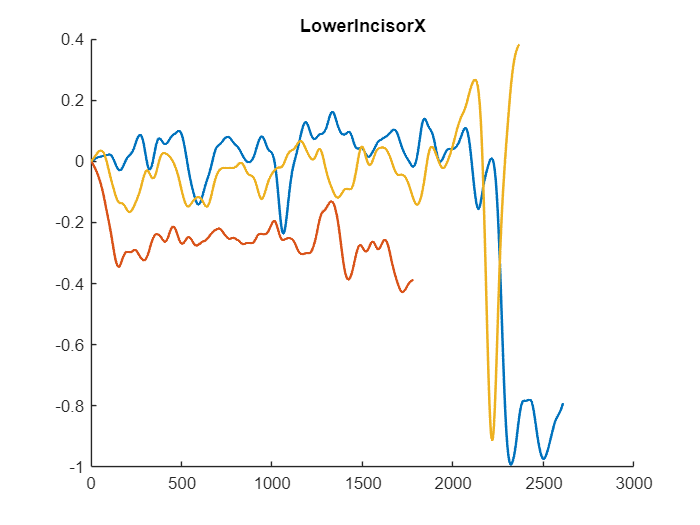

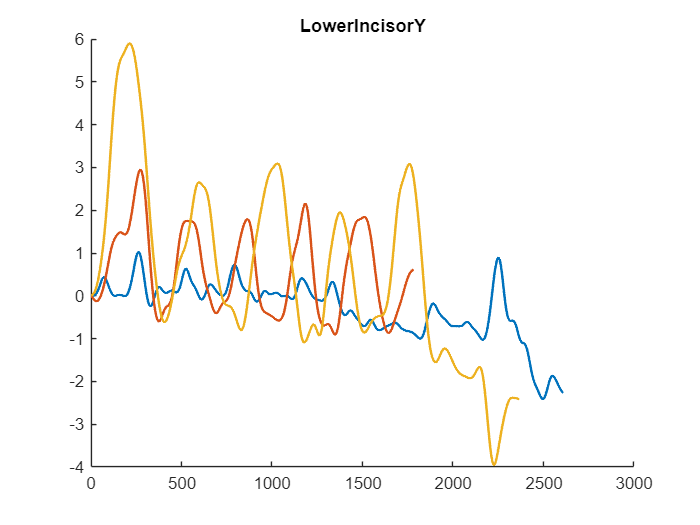

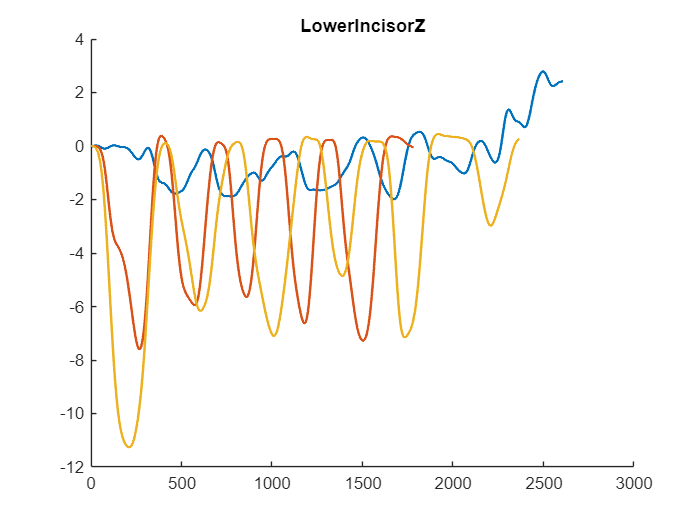

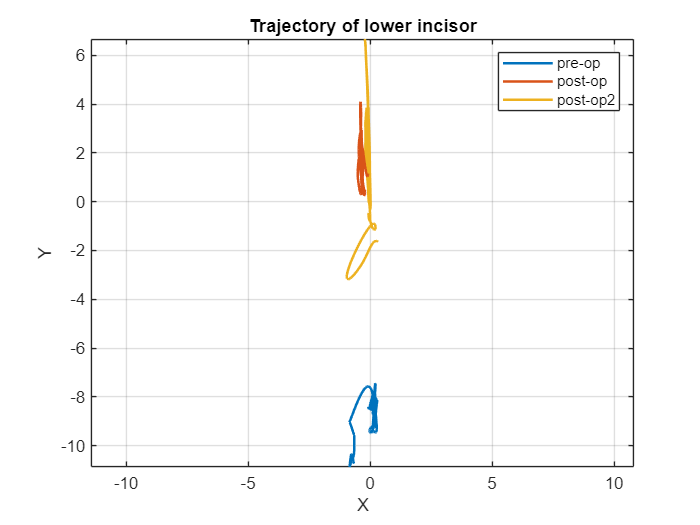


view3KeyPointsDataComparison(m_preopKeyGeomagicPoints, m_postopKeyGeomagicPoints, m_postop2KeyGeomagicPoints);

% Remove path
rmpath(genpath('.\Motion'));
rmpath(genpath('.\Registration'));
rmpath(genpath('.\SVD'));
rmpath(genpath('.\KeyPoints'));